**Neidys Marioly Vargas Montilva**

**Ejercicio 2**

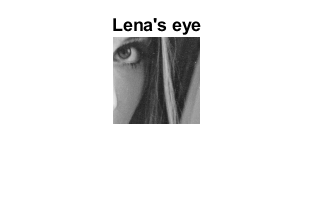

load lena512.mat
lenarec=lena512(252:338,318:404); 
figure(1);
imshow(uint8(lenarec))
title("Lena's eye");

b = de2bi(lenarec,8,'left-msb'); % Convert the samples from uint8 to binary
b = b';     
bits = b(:);

bits2send = bits';
Fs= 96000;
mp= 10;
%No_bits= 8712;
Baud_rate= Fs/mp   %Symbols per second

Baud_rate = 9600

Bit_rate=Baud_rate % bits/s

Bit_rate = 9600

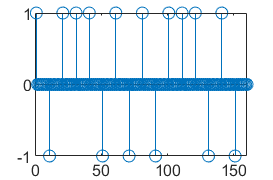

Ts=1/Fs;
% The bit rate is Rb= Rs= Fs / mp, because 1 bit= 1 symbol and  every symbol has mp
% samples per bit

n= 0:(mp-1);
w = pi/mp;
hs = sin(w*n);

pnrz=ones(1,mp);

s1=bits;
s1(s1==0)=-1;
s=zeros(1,numel(s1)*mp);
s(1:mp:end)=s1; %Impulse train
stem(s(1:mp*16))

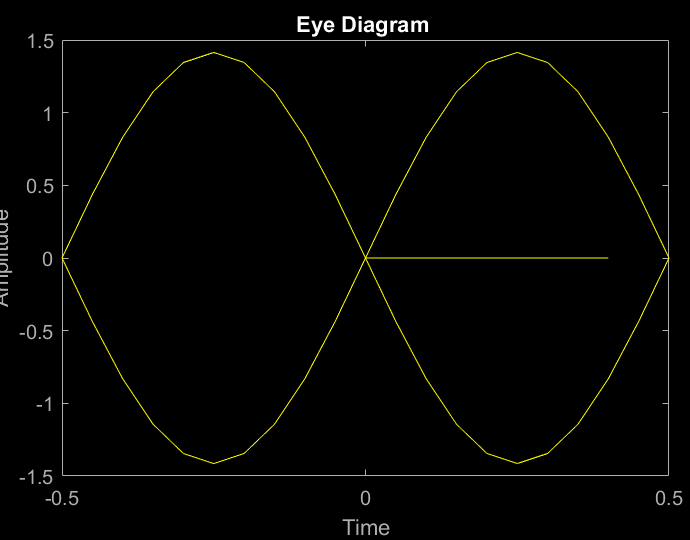


xPNRZ_hs=conv(hs,s); %Pulse half sine
xPNRZ=conv(pnrz,s); %Pulse rectangular

figure();
pow = sum(xPNRZ_hs.^2)/numel(xPNRZ_hs);
pow_Deseada = 1;
xPNRZ_hs = sqrt(pow_Deseada/pow)*xPNRZ_hs;
eyediagram(xPNRZ_hs,2*mp);

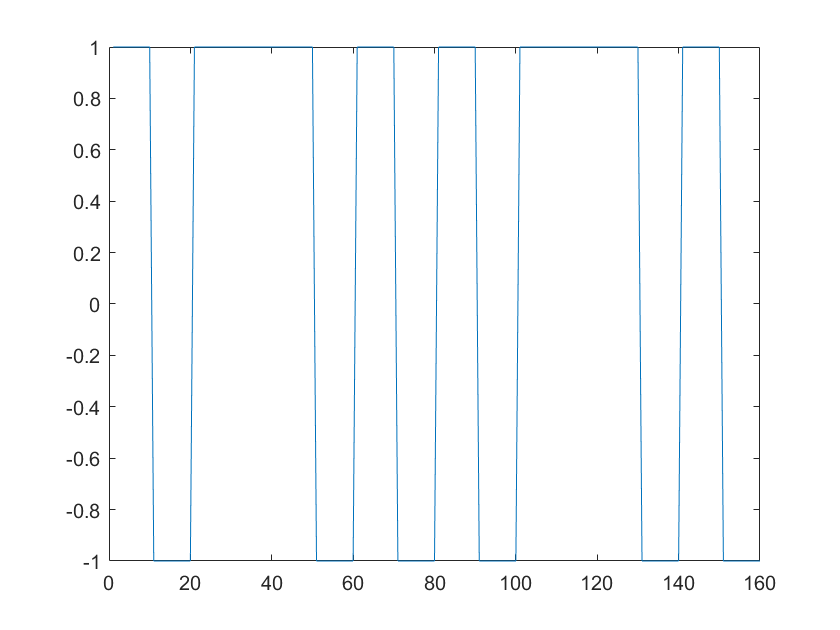

figure();
plot(xPNRZ(1:mp*16))

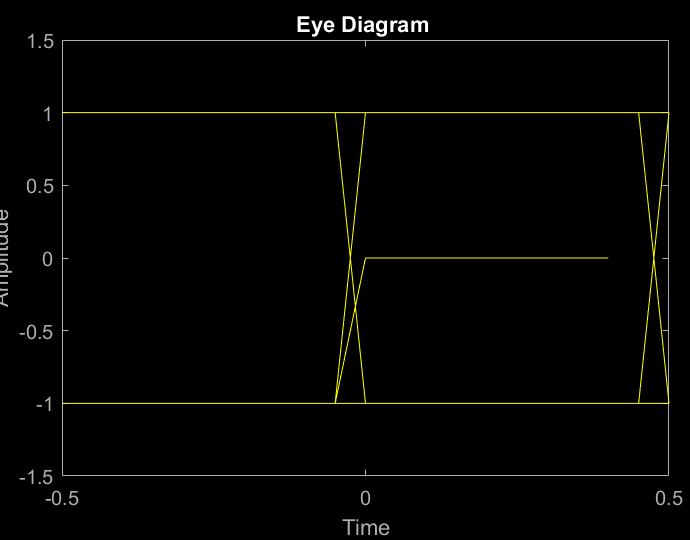

pow = sum(xPNRZ.^2)/numel(xPNRZ);
pow_Deseada = 1;
xPNRZ = sqrt(pow_Deseada/pow)*xPNRZ;
eyediagram(xPNRZ,2*mp);

## ejercicio 3

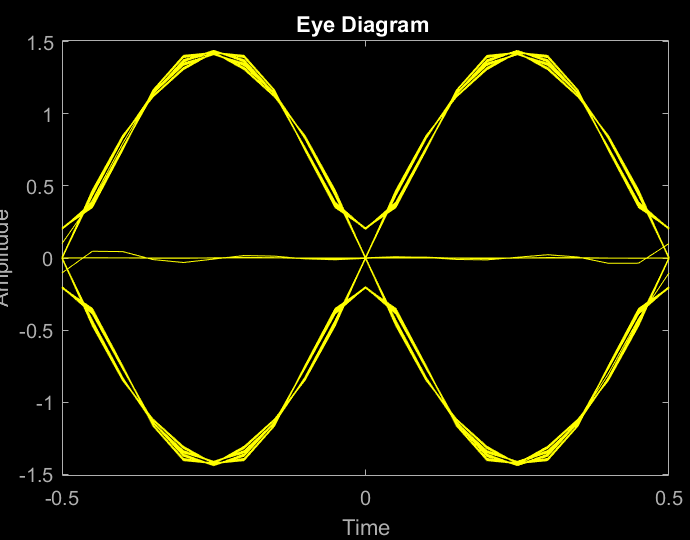

orden=60;     % Orden del Filtro 
f=   [0 0.4 0.4 1];  % Vector de Frecuencias
m= [1 1 0 0]; % Vector de Magnitudes 
f1 = fir2(orden,f,m);  % Coeficientes del Filtro usando FIR2( ) 
%fvtool(f1);    
 
xPNRZ_filtrado_f1 = conv(xPNRZ_hs,f1);
eyediagram(xPNRZ_filtrado_f1,2*mp);

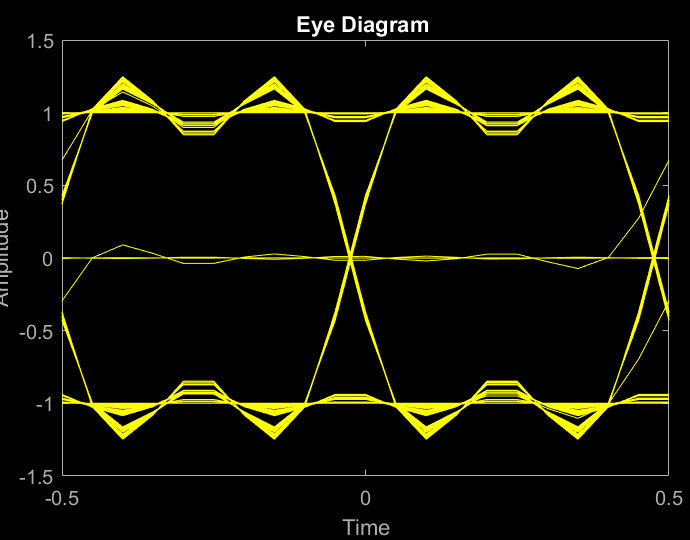


xPNRZ_filtrado_f2 = conv(xPNRZ,f1);
eyediagram(xPNRZ_filtrado_f2,2*mp);

## ejercicio 4

pow = sum(xPNRZ_filtrado_f1.^2)/numel(xPNRZ_filtrado_f1);
pow_Deseada = 1;
xPNRZ_filtrado_f1 = sqrt(pow_Deseada/pow)*xPNRZ_filtrado_f1;
xPNRZ_filtrado_f1_1W_pot = sum(xPNRZ_filtrado_f1.^2)/numel(xPNRZ_filtrado_f1)

xPNRZ_filtrado_f1_1W_pot = 1.0000

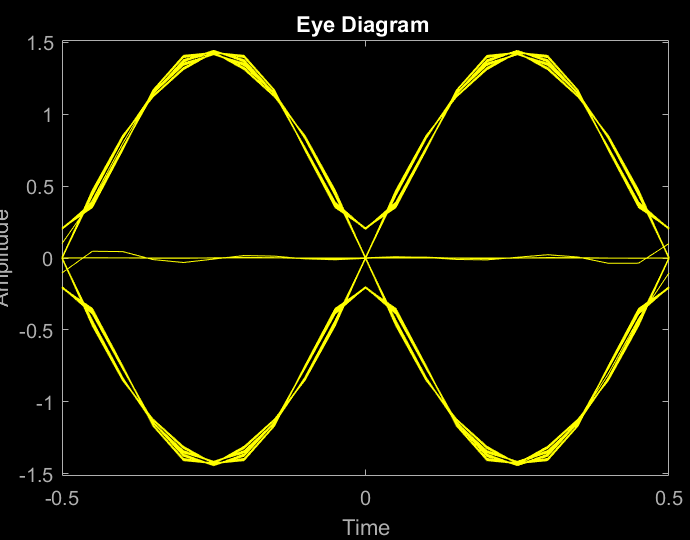

eyediagram(xPNRZ_filtrado_f1,2*mp);



pow = sum(xPNRZ_filtrado_f2.^2)/numel(xPNRZ_filtrado_f2);
pow_Deseada = 1;
xPNRZ_filtrado_f2 = sqrt(pow_Deseada/pow)*xPNRZ_filtrado_f2;
xPNRZ_filtrado_f2_1W_pot = sum(xPNRZ_filtrado_f2.^2)/numel(xPNRZ_filtrado_f2)

xPNRZ_filtrado_f2_1W_pot = 1.0000

eyediagram(xPNRZ_filtrado_f2,2*mp);


## ejercicio 5

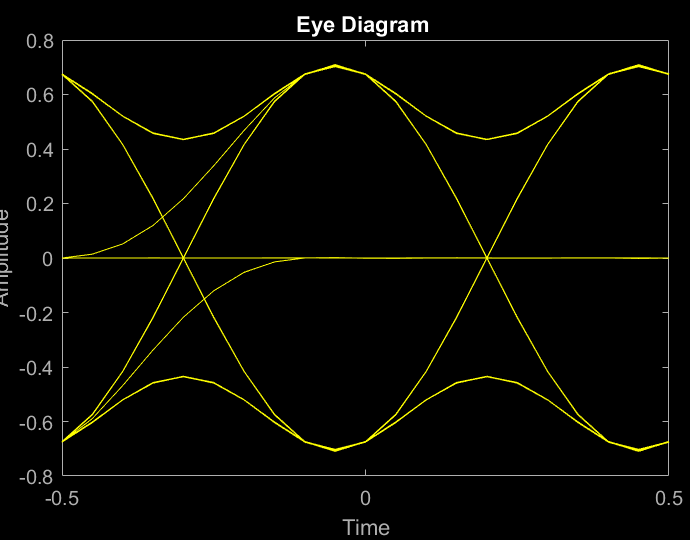

Match_filter1 = fliplr(hs);
Match_filter2 = fliplr(pnrz);

Const11 =conv(xPNRZ_filtrado_f1,Match_filter1)/mp;
Const22 =conv(xPNRZ_filtrado_f2,Match_filter2)/mp;

eyediagram(Const11,2*mp);

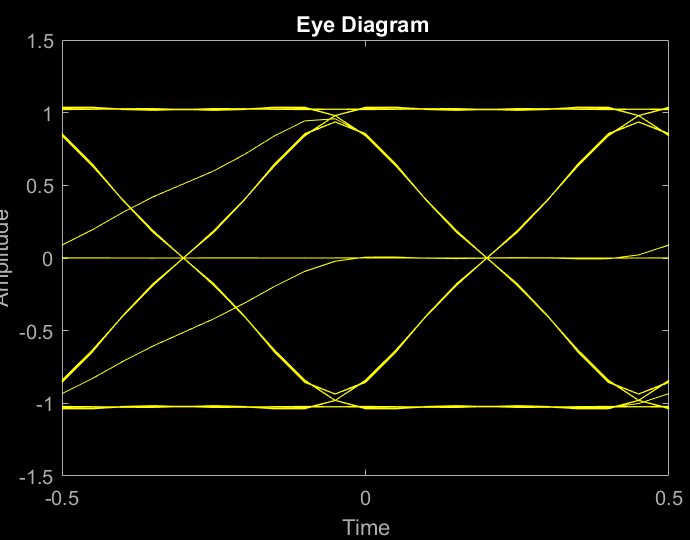

eyediagram(Const22,2*mp);

## ejercicio 6

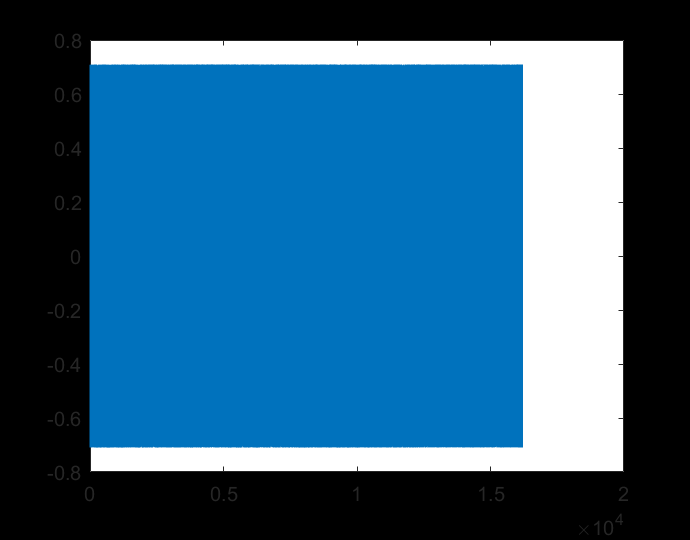

delay_signal = orden/2 + numel(hs)/2; %calculate the signal delay, channel delay + match filter delay
start_recovery_count = delay_signal + mp/2;

PNRZ_recovery_hs = Const11(start_recovery_count:mp:end);
PNRZ_recovery_rec = Const22(start_recovery_count:mp:end);

PNRZ_recovery_hs = PNRZ_recovery_hs(1:numel(bits2send));
PNRZ_recovery_rec = PNRZ_recovery_rec(1:numel(bits2send));
%Decition_treshold_PNRZ = 0;

plot(PNRZ_recovery_hs);
title('hs pulse sampled');

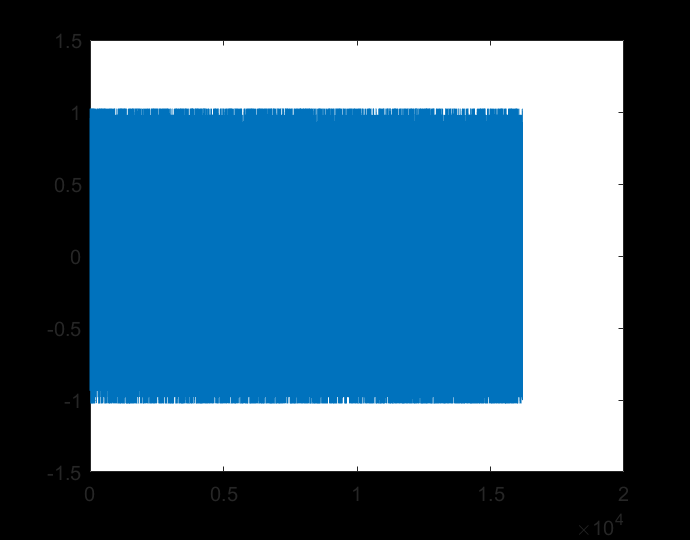


plot(PNRZ_recovery_rec);
title('rec pulse sampled');

## ejercicio 7

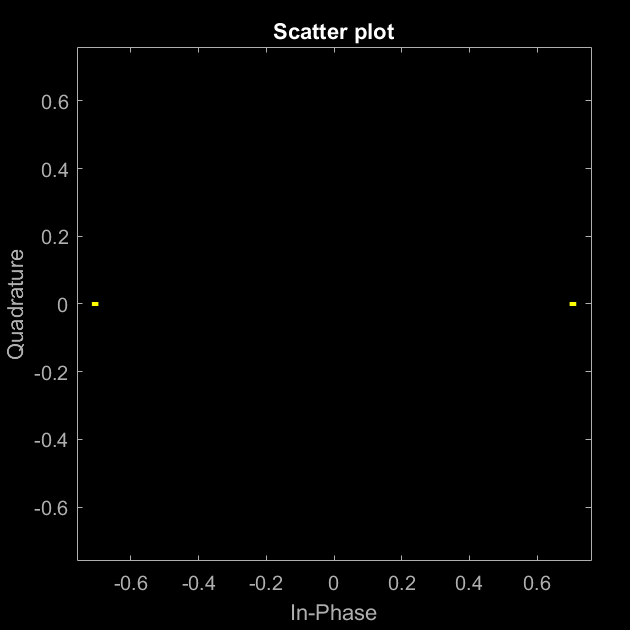

scatterplot(PNRZ_recovery_hs);

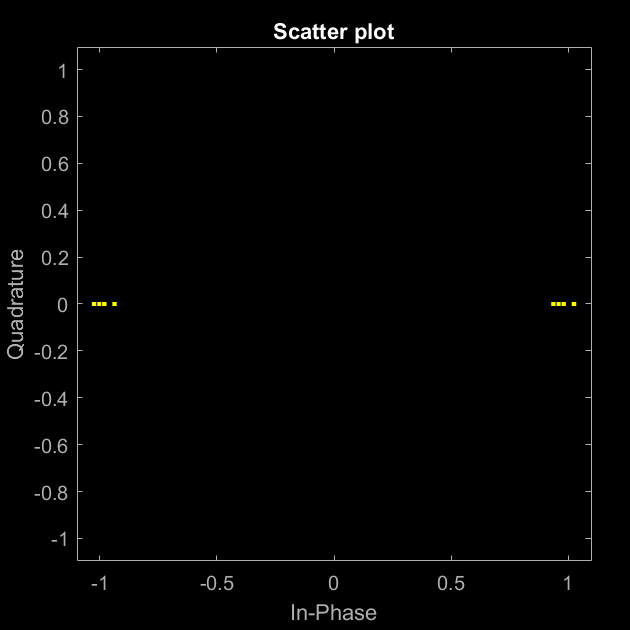

scatterplot(PNRZ_recovery_rec);

## ejercicio 8

bits_RX_PNRZ_1 = zeros(1,numel(bits2send));
bits_RX_PNRZ_2 = zeros(1,numel(bits2send));


xPNRZ_f_m1 = PNRZ_recovery_hs

xPNRZ_f_m1 =     0.7071   -0.7093    0.7059    0.7026    0.7061   -0.7094    0.7087   -0.7092    0.7087   -0.7094    0.7061    0.7026    0.7061   -0.7094    0.7087   -0.7092    0.7087   -0.7094    0.7057    0.7024    0.7031    0.7024    0.7052   -0.7092    0.7059    0.7061   -0.7055   -0.7029   -0.7026   -0.7026   -0.7024   -0.7057    0.7090   -0.7090    0.7057    0.7024    0.7031    0.7024    0.7057   -0.7094    0.7083   -0.7094    0.7057    0.7024    0.7026    0.7022    0.7022    0.7026    0.7029    0.7059


xPNRZ_f_m2 = PNRZ_recovery_rec

xPNRZ_f_m2 =     0.9578   -0.9360    0.9804    1.0226    0.9806   -0.9364    0.9364   -0.9368    0.9364   -0.9364    0.9806    1.0226    0.9806   -0.9364    0.9364   -0.9368    0.9364   -0.9364    0.9801    1.0231    1.0243    1.0231    0.9797   -0.9356    0.9797    0.9793   -0.9793   -1.0235   -1.0239   -1.0239   -1.0231   -0.9801    0.9360   -0.9360    0.9801    1.0231    1.0243    1.0231    0.9801   -0.9364    0.9359   -0.9364    0.9801    1.0231    1.0239    1.0235    1.0235    1.0239    1.0235    0.9797



bits_RX_PNRZ_1(xPNRZ_f_m1 > (max(PNRZ_recovery_hs)/2)) = 1;   %Umbral +
bits_RX_PNRZ_2(xPNRZ_f_m2 > (max(PNRZ_recovery_rec)/2)) = 1;   %Umbral +


xPNRZ_BER_1 = (sum(xor(bits2send,bits_RX_PNRZ_1))/numel(bits2send)) * 100

xPNRZ_BER_1 = 0

xPNRZ_BER_2 = (sum(xor(bits2send,bits_RX_PNRZ_2))/numel(bits2send)) * 100

xPNRZ_BER_2 = 0

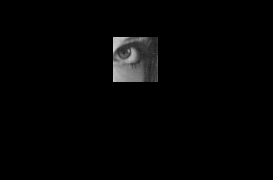



bitsM1 = reshape(bits_RX_PNRZ_1,8,87*87);
bitsM1 = bitsM1';
decval1 = bi2de(bitsM1,'left-msb');
lenaRS1 = reshape(decval1, size(lenarec));
imshow(uint8(lenaRS1))


bitsM1 = reshape(bits_RX_PNRZ_2,8,87*87);
bitsM1 = bitsM1';
decval1 = bi2de(bitsM1,'left-msb');
lenaRS1 = reshape(decval1, size(lenarec));
imshow(uint8(lenaRS1))

Al analizar las señales obtenidas  en el eyediagram podemos apreciar la variacion entre las constalaciones, por lo que se puede ser capaz de analizar el comportamiento de los filtros y las señales.